
% parameters that define the plant
m=0.5;  % pendulum mass
M=0.5;  % cart mass
g=10;   % gravitational constant
L = 1;  % pendulum length

% state description of the plant
A =  [0  1   0   0; 
     0   0  -m*g/M 0;
     0   0   0   1;
     0   0  (M+m)*g/M/L 0];
B =  [0; 1/M; 0 ;-1/M/L];
C =  [1 0 0 0];
D =  0;

P = ss(A,B,C,D);

% % pole-zero constellation of the plant
% figure(1)
% clf
% pzmap(P)
% set(findall(gcf,'type','line'),'linewidth',2)
% 
% % bode plot of the plant
w = logspace(-2,2,200);
% [mag,phase] = bode(P,w);
% mag = squeeze(mag);phase = squeeze(phase);
% 
% figure(2)
% clf
% subplot(2,1,1)
% loglog(w,mag)
% ylabel('magnitude')
% title('Bode plots, inverted pendulum')
% subplot(2,1,2)
% semilogx(w,phase)
% ylabel('phase, degrees')
% set(findall(gcf,'type','line'),'linewidth',2)
%  
%  
% % Nyquist plot of the plant 
% 
% [re,im] = nyquist(P,w);
% re = squeeze(re);im = squeeze(im);
% 
% figure(3)
% clf
% plot(re,im,'-',re,-im,'--')
% title('Nyquist plot of inverted pendulum')
% xlabel('real')
% ylabel('imaginary')
% axis([-5 5 -5 5])
% set(findall(gcf,'type','line'),'linewidth',2)
% 
% % positive and negative root loci of the plant
% figure(4)
% clf
% rlocus(P)
% title('root locus for k>0')
% set(findall(gcf,'type','line'),'linewidth',2)
% 
% figure(5)
% clf
% rlocus(-P)
% title('root locus for k<0')
% set(findall(gcf,'type','line'),'linewidth',2)
% 
% % design controller with position feedback only
% %
% % desired state feedback and observer eigenvalues

psf =  [-1+j, -1-j, -5, -6]

psf =   -1.0000 + 1.0000i  -1.0000 - 1.0000i  -5.0000 + 0.0000i  -6.0000 + 0.0000i


pobs = 2*psf

pobs =   -2.0000 + 2.0000i  -2.0000 - 2.0000i -10.0000 + 0.0000i -12.0000 + 0.0000i




% state feedback and observer gains (use the "place" command)

K = place(A,B,psf);
L = place(A',C',pobs)';

% state space description of compensator with one measurement
A_C1 =  A- B*K -L*C;
B_C1 =  L;
C_C1 =  K;
D_C1 =  0

D_C1 = 0

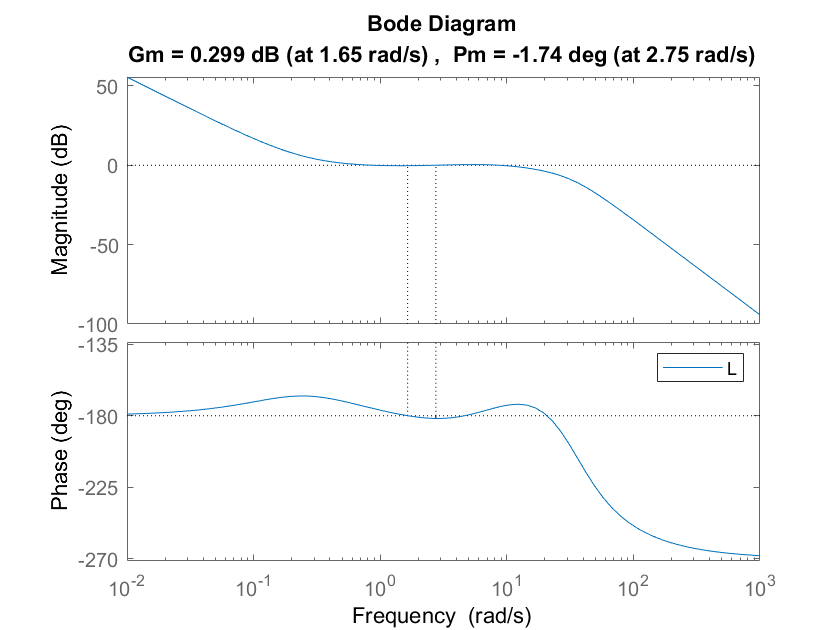

Cobs1 = ss(A_C1,B_C1,C_C1,D_C1);

% open loop, sensitivity, and comp. sensitivity functions
Lobs1 =  P*Cobs1;
S1 = 1/(1+Lobs1);
T1 = 1- S1;

figure;
margin(Lobs1);
legend('L');

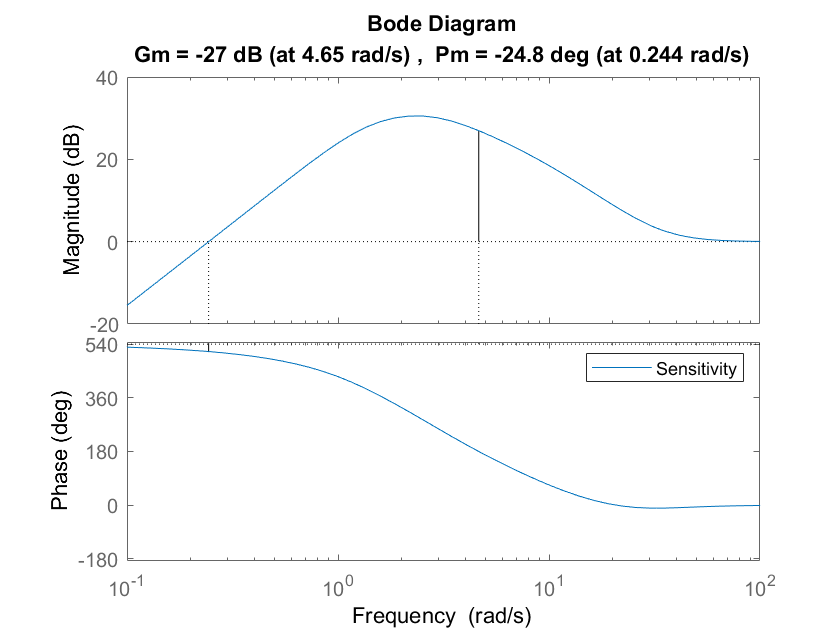

figure;
margin(S1);
legend('Sensitivity');


% check poles of compensator to see if they are stable
compensator_poles = eig(A_C1)

compensator_poles =  -24.4967 +23.6479i
 -24.4967 -23.6479i
  13.1615 + 0.0000i
  -3.1681 + 0.0000i


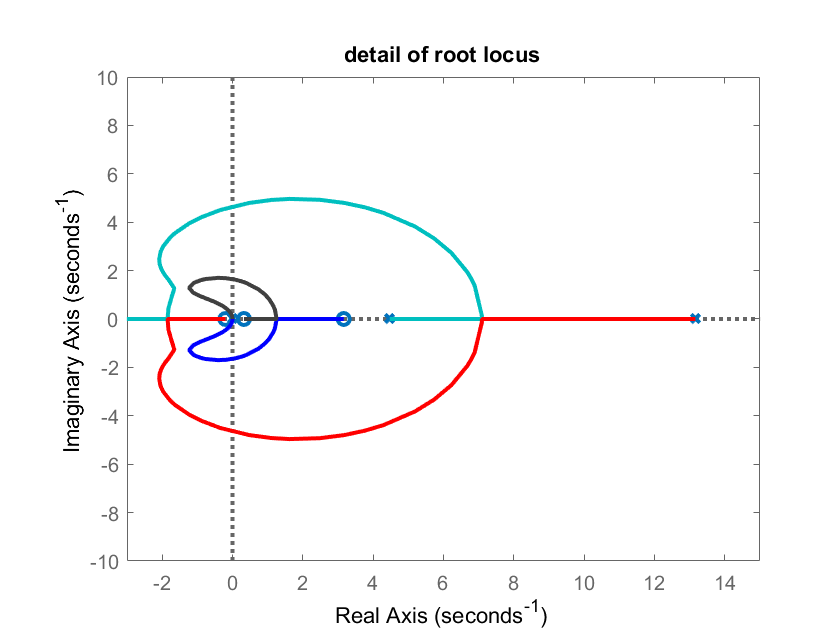



figure(6)
clf
rlocus(Lobs1)
axis([-3  15 -10 10])
title('detail of root locus')
set(findall(gcf,'type','line'),'linewidth',2) 

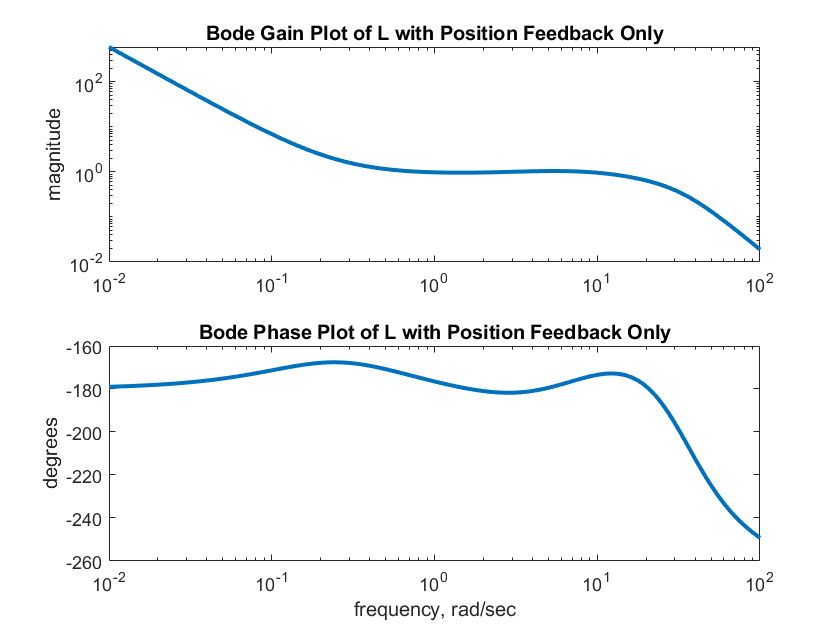


% Bode plot of the open loop L
[mag,phase] = bode(Lobs1,w);
mag = squeeze(mag);
phase = squeeze(phase);
figure(7)
clf
subplot(2,1,1)
loglog(w,mag)
%xlabel('frequency, rad/sec')
ylabel('magnitude')
title('Bode Gain Plot of L with Position Feedback Only')
subplot(2,1,2)
semilogx(w,phase)
xlabel('frequency, rad/sec')
ylabel('degrees')
title('Bode Phase Plot of L with Position Feedback Only')
set(findall(gcf,'type','line'),'linewidth',2)

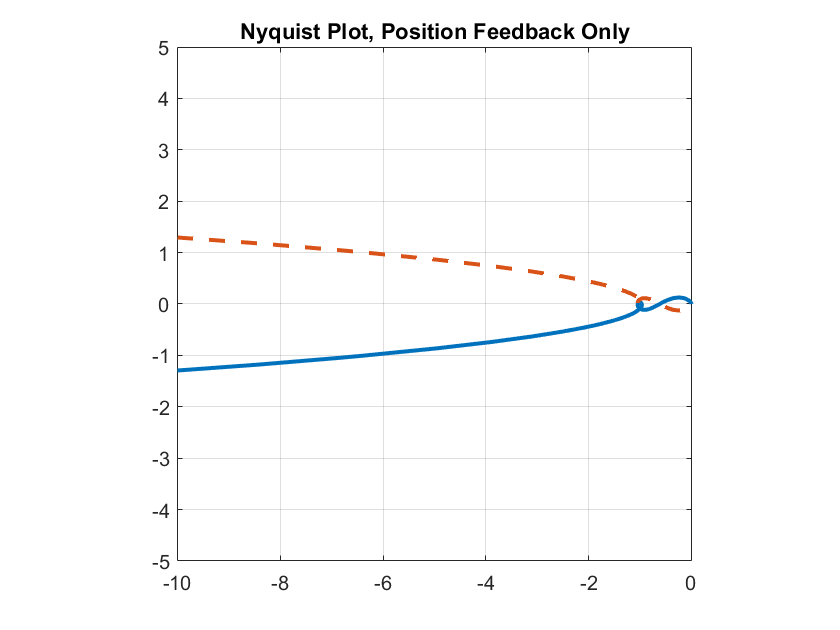



% Nyquist plot
[re,im] = nyquist(Lobs1);
re = squeeze(re);im = squeeze(im);
figure(8)
clf
plot(re,im,'-',re,-im,'--')
axis([-10 0 -5 5])
axis('square')
grid
title('Nyquist Plot, Position Feedback Only')
set(findall(gcf,'type','line'),'linewidth',2)

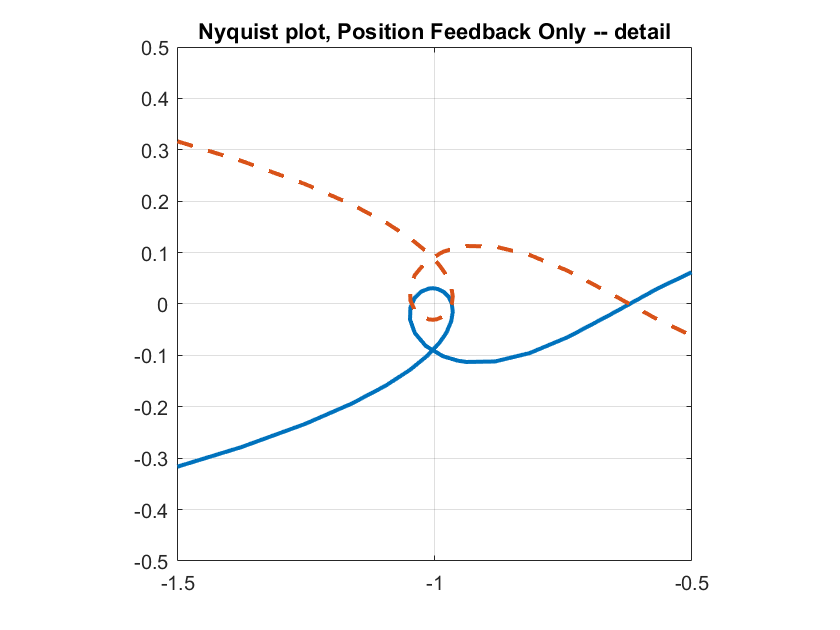


% Nyquist plot -- a detail near the critical point
[re,im] = nyquist(Lobs1);
re = squeeze(re);im = squeeze(im);
figure(9)
clf
plot(re,im,'-',re,-im,'--')
axis('square')
grid
axis([-1.5 -0.5  -0.5  0.5])
title('Nyquist plot, Position Feedback Only -- detail')
set(findall(gcf,'type','line'),'linewidth',2)

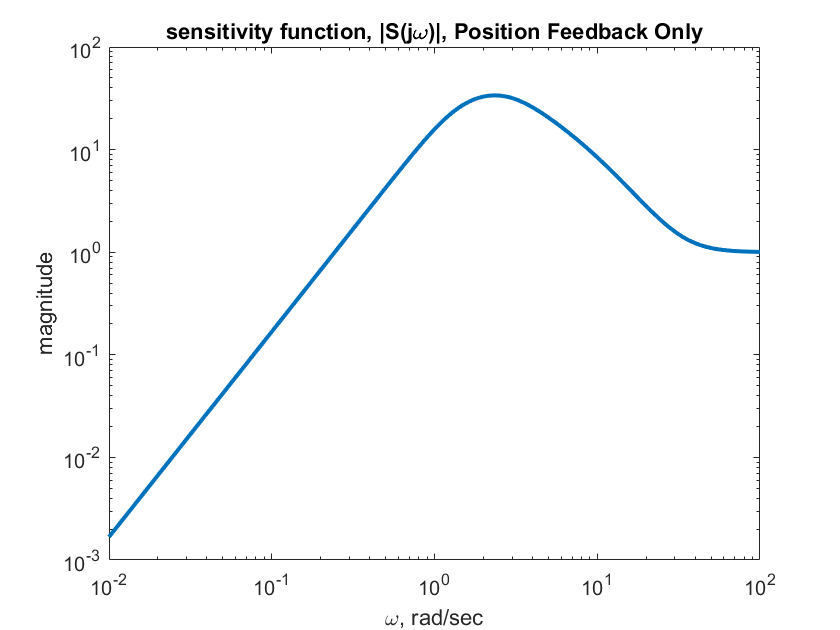


% Bode plot of the sensitivity function 

[mS1,pS1] = bode(S1,w);
mS1 = squeeze(mS1);pS1 = squeeze(pS1);
figure(10)
clf
loglog(w,mS1)
%grid
xlabel('\omega, rad/sec')
ylabel('magnitude')
title('sensitivity function, |S(j\omega)|, Position Feedback Only')
set(findall(gcf,'type','line'),'linewidth',2)


% add a precompensator to achieve steady state tracking
% and plot both pendulum angle and cart position 
% need to change the C and D matrices to provide both outputs
G =  inv(C/(-A+B*K)*B)

G = -3.0000

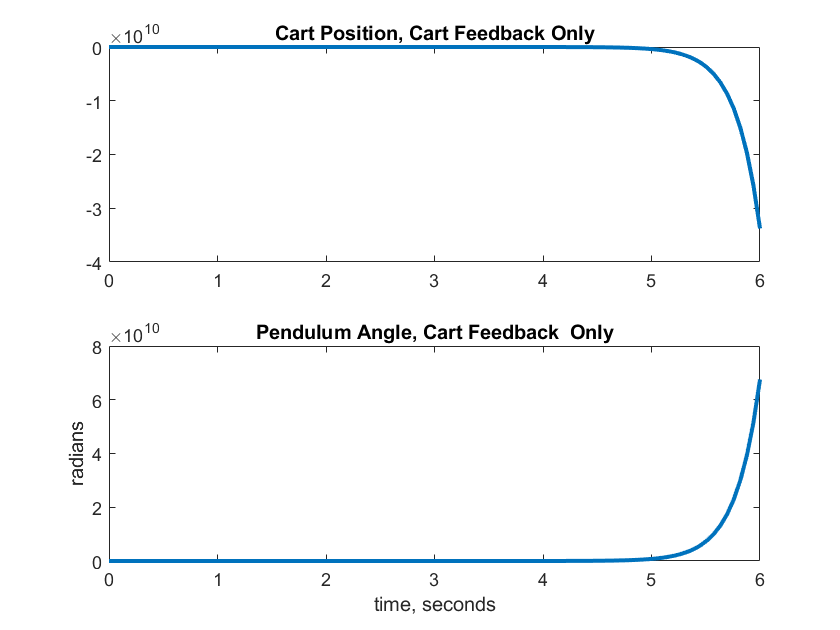

Cboth = [1 0 0 0;0 0 1 0];
Dboth = zeros(2,1);  

% closed loop system that maps the reference through the precompensator and
% the system with state feedback
TsfG = ss(A,B,Cboth,Dboth)*G;

t = linspace(0,6);
y = step(TsfG,t);

figure(11)
clf
subplot(2,1,1)
plot(t,y(:,1))
title('Cart Position, Cart Feedback Only')
subplot(2,1,2)
plot(t,y(:,2))
title('Pendulum Angle, Cart Feedback  Only')
ylabel('radians')
xlabel('time, seconds')
set(findall(gcf,'type','line'),'linewidth',2)

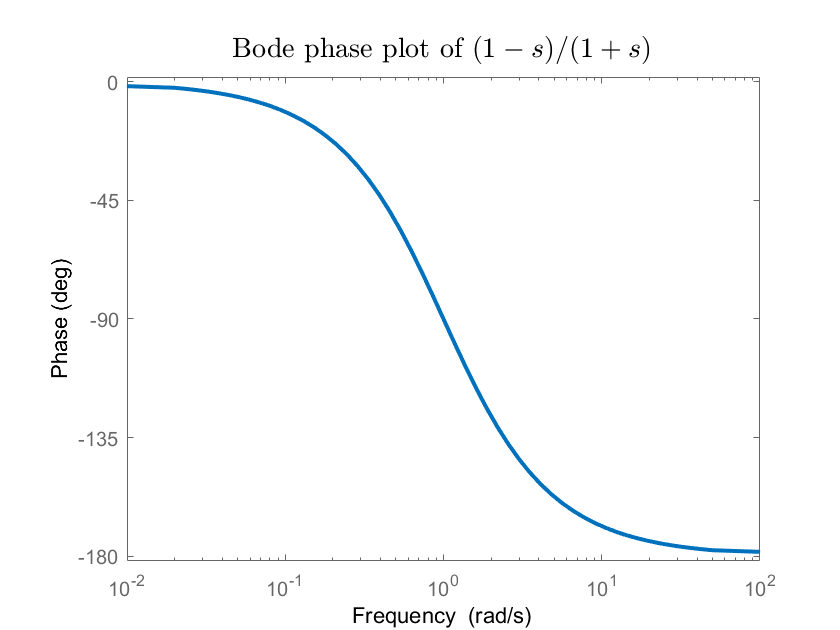



% plot out the phase lag due to a NMP zero at s = 1
num = [-1 1];
den = [1 1];
allpass = tf(num,den);

figure(12)
clf
h=bodeplot(allpass);
p = getoptions(h);
p.MagVisible = 'off';
p.PhaseWrapping = 'off'; 
p.PhaseMatching = 'on';
p.PhaseMatchingFreq=0;
setoptions(h,p); % Update the Bode plot. 
set(findall(gcf,'type','line'),'linewidth',2)
h = title('Bode phase plot of  $(1-s)/(1+s)$');
 set(h,'interpreter','latex','fontsize',14); 

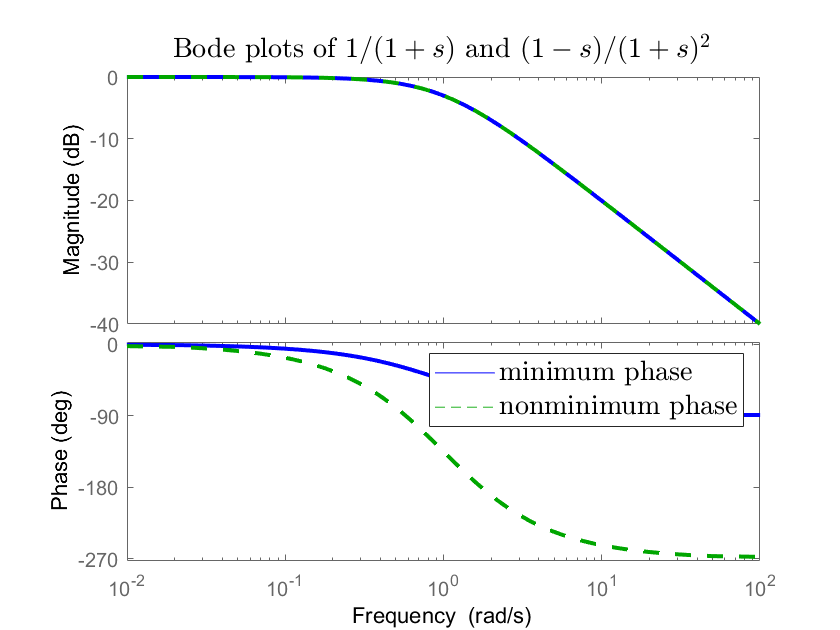



% plot the phase lag of the system 1/(s+1) with and without an additional
% NMP zero added w/o changing the gain (1-s)/(s+1)^2

num_MP = 1;den_MP = [1 1];
num_NMP = [-1 1];den_NMP = [1 2 1];

G_MP = tf(num_MP,den_MP);
G_NMP = tf(num_NMP,den_NMP);
figure(13)
clf
h=bodeplot(G_MP,'b-',G_NMP,'g--');
p = getoptions(h);
p.PhaseWrapping = 'off'; 
p.PhaseMatching = 'on';
p.PhaseMatchingFreq=0;
setoptions(h,p); % Update the Bode plot.
h = legend('minimum phase','nonminimum phase');
 set(h,'interpreter','latex','fontsize',14); 
set(findall(gcf,'type','line'),'linewidth',2)
h = title('Bode plots of $1/(1+s)$ and $(1-s)/(1+s)^2$');
 set(h,'interpreter','latex','fontsize',14); 	

% 	
% 
% 
% 
% % plot step response of system to an input disturbance
% % with state feedback
% % 
% 
% Ad_sf =  
% Bd_sf =  
% Cd_sf =  
% Dd_sf =  
% Td_sf = ss(Ad_sf,Bd_sf,Cd_sf,Dd_sf);
% 
% ysf_dist = step(Td_sf,t);
% 
% % plot step response of system to a disturbance
% % with an observer
% Ad_obs =  
% Bd_obs =  
% Cd_obs =  
% Dd_obs =  
% Td_obs = ss(Ad_obs,Bd_obs,Cd_obs,Dd_obs);
% yobs_dist = step(Td_obs,t); 
% 
% figure(14)
% clf
% subplot(2,1,1)
% plot(t,yobs_dist(:,1),'-',t,ysf_dist(:,1),'--')
% title('Response of Cart Position to Step Disturbance')
% grid
% subplot(2,1,2)
% plot(t,yobs_dist(:,2),'-',t,ysf_dist(:,2),'--')
% title('Response of Pendulum Angle to Step Disturbance')
% ylabel('radians')
% xlabel('time, seconds')
% legend('with observer','state feedback')
% grid
% set(findall(gcf,'type','line'),'linewidth',2)
% 
% % now use both measurements for feedback into the observer
%  
% % compute state feedback and observer gains
% % note that TWO outputs must fed into the observer
% K = place(A,B,psf);
% L = place(A',Cboth',pobs)';
% 
% % state space of Cobs2, the observer based compensator
% % with both outputs
% A_C2 =  
% B_C2 =  
% C_C2 =   
% D_C2 =  
% Cobs2 = ss(A_C2,B_C2,C_C2,D_C2);
% 
% % state space of the scalar open loop and sensitivity functions
% % obtained at the plant input. 
% % L = Cobs2*Pboth, where Pboth is the SITO plant with two outputs (cart and
% % pendulum)
% 
% Pboth = ss(A,B,Cboth,Dboth);
% 
% Lobs2 =  
% Sobs2 = 1/(1+Lobs2);
% [mS2,pS2] = bode(Sobs2,w);
% mS2 = squeeze(mS2);pS2 = squeeze(pS2);
%  
% [mag,phase] = bode(Lobs2,w);
% mag = squeeze(mag);phase = squeeze(phase);
% 
% % Bode plot of the open loop at the plant input
% figure(15)
% clf
% subplot(2,1,1)
% loglog(w,mag)
% %xlabel('frequency, rad/sec')
% ylabel('magnitude')
% title('Bode Gain Plot of L with Cart and Angle  Feedback')
% subplot(2,1,2)
% semilogx(w,phase)
% xlabel('frequency, rad/sec')
% ylabel('degrees')
% title('Bode Phase Plot of L with Cart and Angle  Feedback')
% set(findall(gcf,'type','line'),'linewidth',2)
% 
% % Nyquist plot at the plant input
% 
% [re,im] = nyquist(Lobs2,w);
% re = squeeze(re);im = squeeze(im);
% figure(16)
% clf
% plot(re,im,'-',re,-im,'--')
% title('Nyquist Plot, Two Measurements -- detail')
% axis([-1.5 -0.5  -0.5  0.5])
% axis('square')
% grid
% set(findall(gcf,'type','line'),'linewidth',2)
% 
% % sensitivity functions at the plant input, with 1 and 2 measurements
% figure(17)
% clf
% loglog(w,mS2,'-',w,mS1,'--')  
% axis([.01 100 .01 100])
% legend('2 measurements','1 measurement')
% xlabel('\omega, rad/sec')
% title('sensitivity functions')
% set(findall(gcf,'type','line'),'linewidth',2)